# Higher Order Derivatives--Cobb Douglas

We have the following general form for the Cobb-Douglas Production Function


$$Y(K,L) = K^{\alpha} \cdot L^{\beta}$$


The first order condition is


$$\frac{dY(K,L)}{dL} = (\beta) \cdot K^{\alpha} \cdot L^{\beta-1}$$


The derivative we have obtained is just another function. We can take additional derivatives with respect to this function. 


$$\frac{\text{d}^2 Y(K,L)}{dL^2} = (\beta)\cdot(\beta-1)\cdot K^{\alpha} \cdot L^{\beta-2}$$


Matlab symbolic toolbox gives us the same answer:

syms L K0 alpha beta
f(L, K0, alpha) = K0^(alpha)*L^(beta);
first_deri = diff(f, L)

$$first\_deri(L, K0, alpha) = {K_{0}}^{\alpha }\,L^{\beta -1}\,\beta$$

second_deri = diff(diff(f, L),L)

$$second\_deri(L, K0, alpha) = {K_{0}}^{\alpha }\,L^{\beta -2}\,\beta \,\left(\beta -1\right)$$

You can specify an additional parameter for the matlab *diff *function, if we want to take multiple derivatives:

syms L K0 alpha beta
f(L, K0, alpha) = K0^(alpha)*L^(beta);
% 5 for 5th derivative
tenth_deri = diff(f, L, 5)

$$tenth\_deri(L, K0, alpha) = {K_{0}}^{\alpha }\,L^{\beta -5}\,\beta \,\left(\beta -1\right)\,\left(\beta -2\right)\,\left(\beta -3\right)\,\left(\beta -4\right)$$

## Curvature and Second Derivative, Concave Function

Let's graph out the second derivative when $\beta=0.5$. The production function is concave (concave down). 

alpha = 0.5;
beta = 0.5;
K0 = 1;
% Note that we have 1 symbolic variable now, the others are numbers
syms L
f(L) = K0^(alpha)*L^(beta);
% note f_diff1_L >= 0 always
f_diff1_L = diff(f, L)

$$f\_diff1\_L(L) = \frac{1}{2\,\sqrt{L}}$$

% note f_diff2_l <= 0 always
f_diff2_L = diff(f, L, 2)

$$f\_diff2\_L(L) = -\frac{1}{4\,L^{3/2}}$$

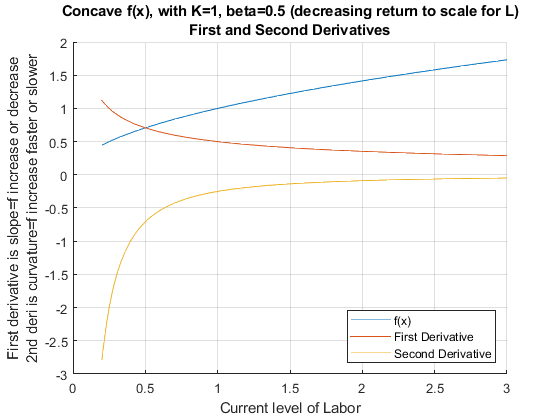

% Start figure
figure();
hold on;
% fplot plots a function with one symbolic variable
fplot(f, [0.2, 3])
fplot(f_diff1_L, [0.2, 3])
fplot(f_diff2_L, [0.2, 3])
title({'Concave f(x), with K=1, beta=0.5 (decreasing return to scale for L)' 'First and Second Derivatives'})
ylabel({'First derivative is slope=f increase or decrease' '2nd deri is curvature=f increase faster or slower'})
xlabel('Current level of Labor')
legend(['f(x)'], ['First Derivative'], ['Second Derivative'], 'Location','SE');
grid on

## Curvature and Second Derivative, Convex Function

Let's graph out the second derivative when $\beta=1.2$. The production function is convex (concave up).

alpha = 0.5;
beta = 1.2;
K0 = 1;
% Note that we have 1 symbolic variable now, the others are numbers
syms L
f(L) = K0^(alpha)*L^(beta);
% Note here f_diff1_L >= 0
f_diff1_L = diff(f, L)

$$f\_diff1\_L(L) = \frac{6\,L^{1/5}}{5}$$

% Note here f_diff2_L >= 0
f_diff2_L = diff(f, L, 2)

$$f\_diff2\_L(L) = \frac{6}{25\,L^{4/5}}$$

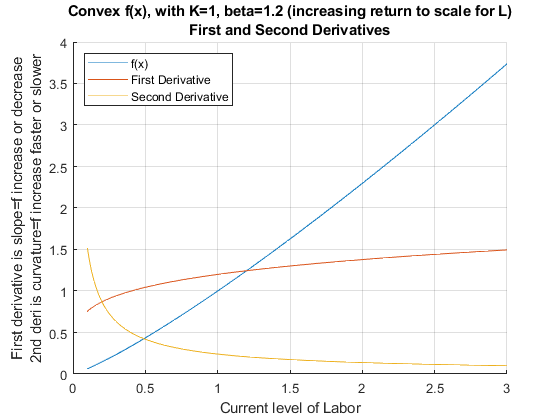

% Start figure
figure();
hold on;
% fplot plots a function with one symbolic variable
fplot(f, [0.1, 3])
fplot(f_diff1_L, [0.1, 3])
fplot(f_diff2_L, [0.1, 3])
title({'Convex f(x), with K=1, beta=1.2 (increasing return to scale for L)' 'First and Second Derivatives'})
ylabel({'First derivative is slope=f increase or decrease' '2nd deri is curvature=f increase faster or slower'})
xlabel('Current level of Labor')
legend(['f(x)'], ['First Derivative'], ['Second Derivative'], 'Location','NW');
grid on